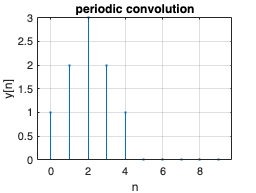

clear;
N = 10;
x = [1, 1, 1, 0, 0, 0, 0, 0, 0, 0];

y = cconv(x, x, N);

n = 0:N-1;
stem(n, y, '.');
xlabel('n');
ylabel('y[n]');
title('periodic convolution');
grid on;


b_k=zeros(1,N)

b_k =      0     0     0     0     0     0     0     0     0     0


for k = 0:N-1
    b_k(k+1)=(1/N)*sum(y.*exp(-1j*2*pi*k*n/N));
end

help cconv

 cconv - Modulo-n circular convolution
    This MATLAB function circularly convolves vectors a and b.

    Syntax
      c = cconv(a,b)
      c = cconv(a,b,n)

    Input Arguments
      a - Input arrays
        vector
      b - Input arrays
        vector
      n - Convolution length
        positive integer

    Output Arguments
      c - Circular convolution
        vector

    Examples
      